# Ecuaciones diferenciales de primer orden

## Ejemplo 1:


$$\frac{d}{\mathrm{d}t}y=-2y,\;\;\;\;\;y\left(0\right)=2$$


#### Resolver la EDO de forma numérica:

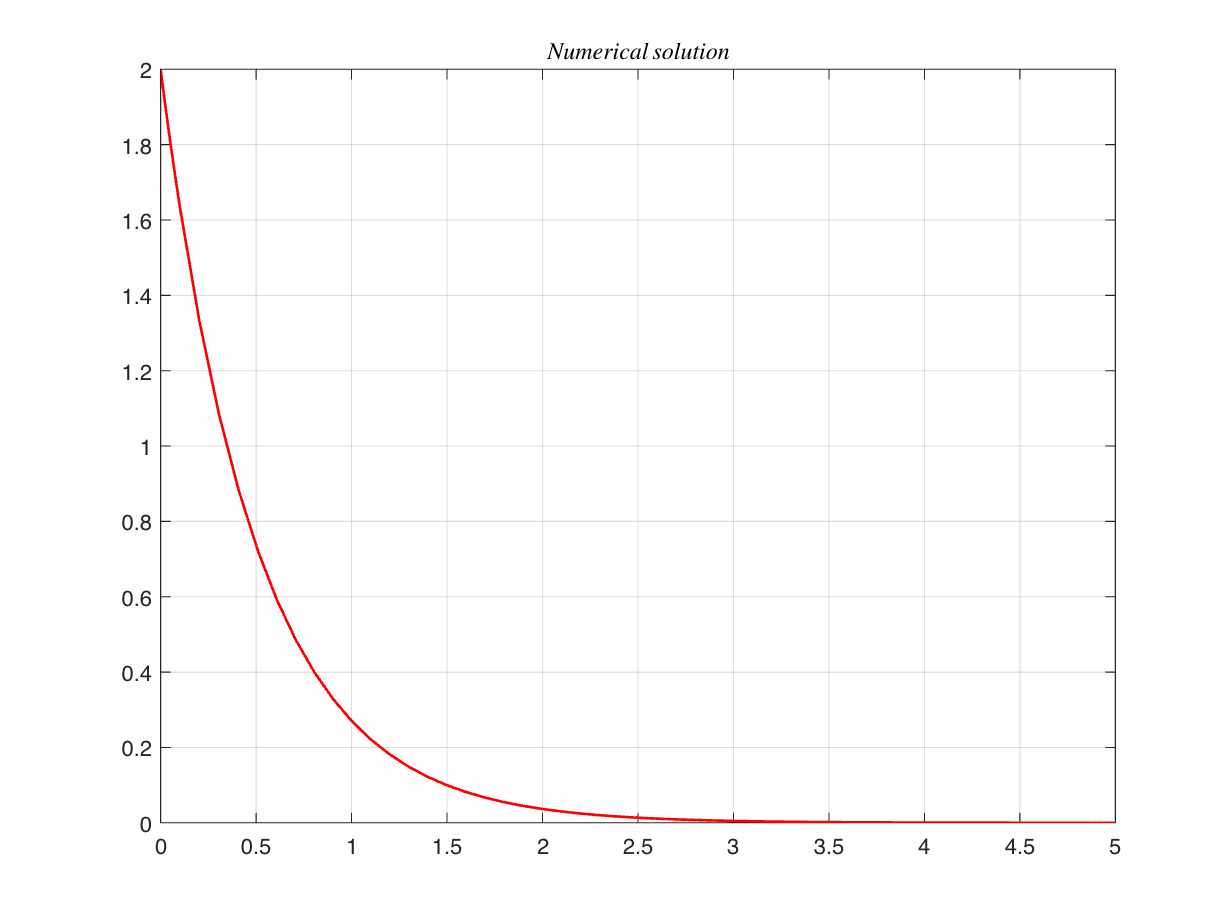

f = @(t, y) (-2.*y);
y0 = 2;
t0 = 0;
tf = 5;

[t, y] = ode45(f, [t0 tf], y0);
plot(t, y, 'r', 'LineWidth', 1.2);
title('$Numerical\,solution$', 'Interpreter','latex')
grid on;

#### Resolver la EDO de forma analítica:

syms y(t)

dy = diff(y, t);
y(t) = dsolve(dy == -2*y, y(0) == 2)

$$y(t) = 2\,{\mathrm{e}}^{-2\,t}$$

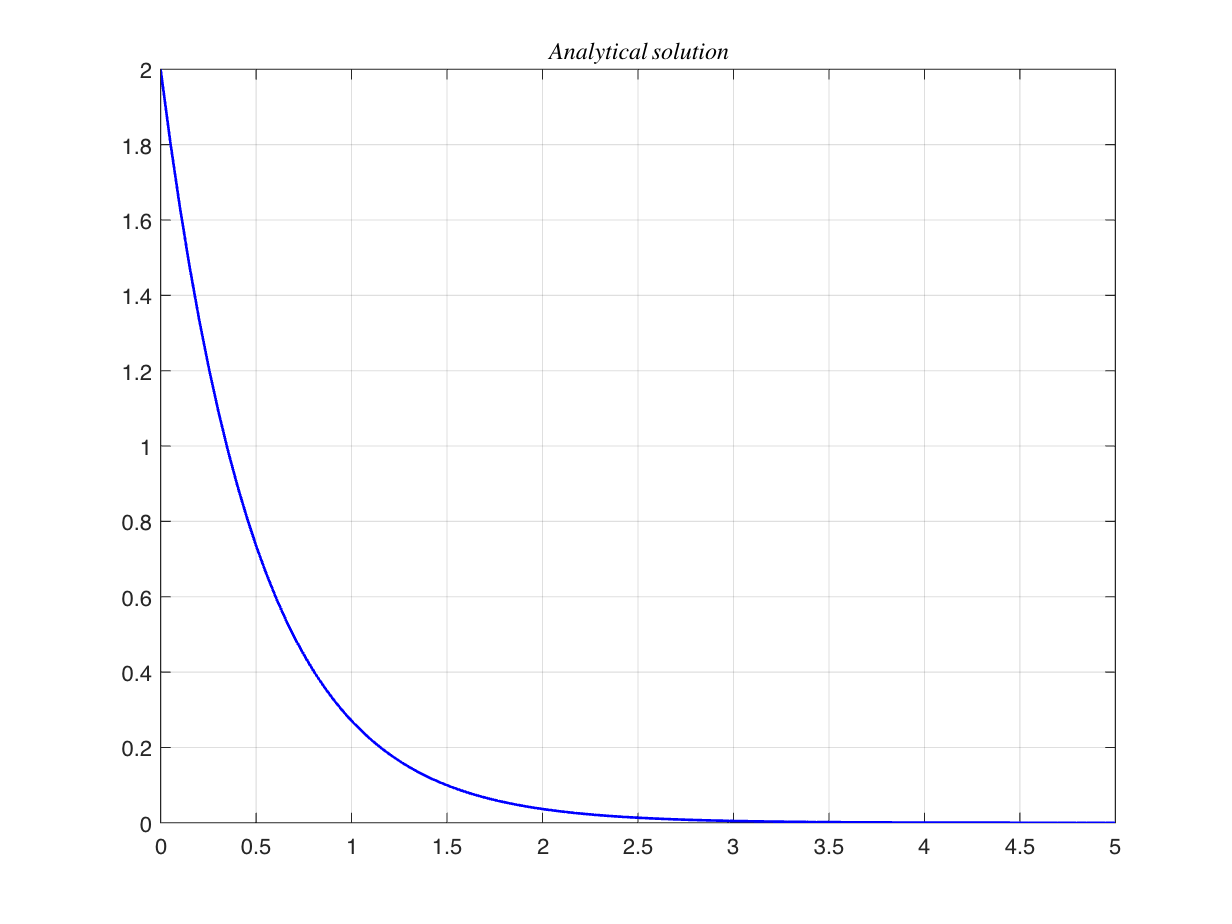

t = linspace(0, 5);
plot(t, y(t), 'b', 'LineWidth', 1.2)
title('$Analytical\,solution$', 'Interpreter','latex')
grid on;

## Ejemplo 2:


$$\frac{d}{\mathrm{d}t}y=2y+e^t ,\;\;\;\;\;y\left(0\right)=1$$


#### Resolver la EDO de forma numérica:

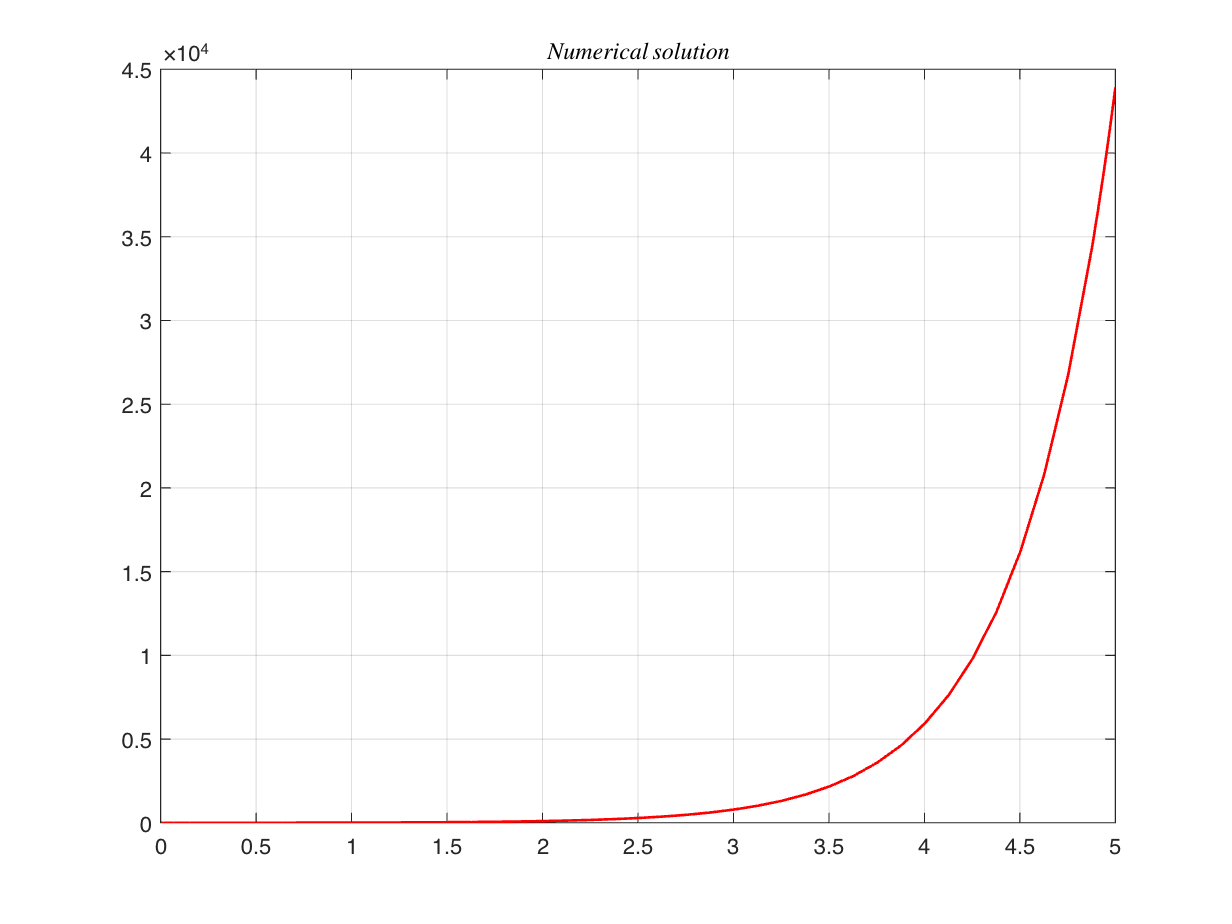

f = @(t, y) (2.*y+exp(t));
y0 = 1;
t0 = 0;
tf = 5;

[t, y] = ode45(f, [t0 tf], y0);
plot(t, y, 'r', 'LineWidth', 1.2);
title('$Numerical\,solution$', 'Interpreter','latex')
grid on;

#### Resolver la EDO de forma analítica:

syms y(t)

dy = diff(y, t);
y(t) = dsolve(dy == 2*y + exp(t), y(0) == 1)

$$y(t) = 2\,{\mathrm{e}}^{2\,t}-{\mathrm{e}}^{t}$$

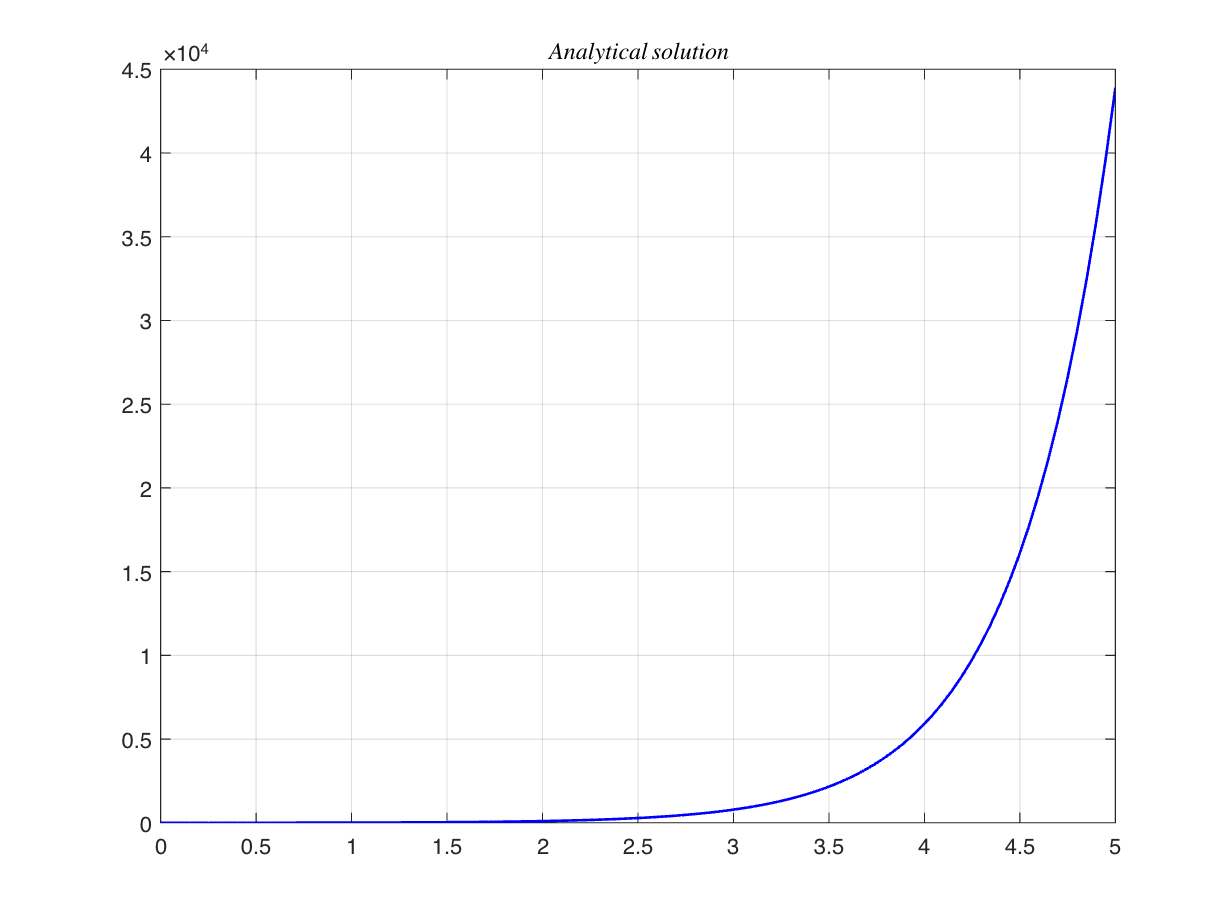

t = linspace(0, 5);
plot(t, y(t), 'b', 'LineWidth', 1.2)
title('$Analytical\,solution$', 'Interpreter','latex')
grid on;